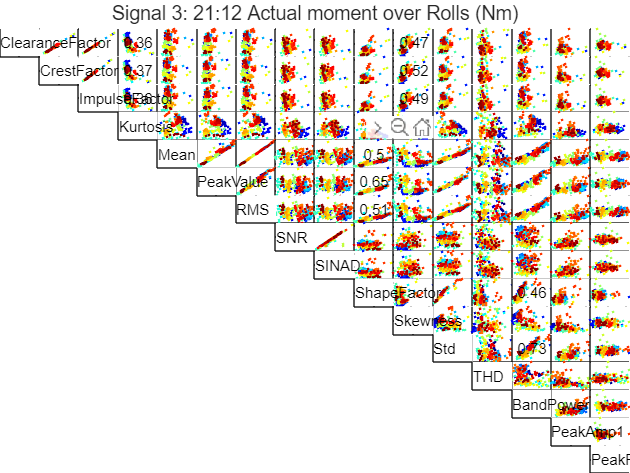

Features = DFD_FeatureTable_TimeDomain;
FeatureNames = FeatureNames_Combined;
lowerR2 = 0.3;
upperR2 = 0.8;
r2ReducedThreshold = 0.9
selectedSignal = 3;
R2 = fnPlotFeatureVsFeature_Array(featureArray, lowerR2, upperR2, selectedSignal, FeatureNames, sensorNames);

disp(num2str(R2, '%.2f  '));

0.00  0.99  1.00  0.36  0.00  0.04  0.00  0.03  0.01  0.25  0.47  0.08  0.02  0.00  0.00  0.00
0.00  0.00  0.99  0.37  0.01  0.01  0.01  0.03  0.01  0.16  0.52  0.03  0.03  0.01  0.01  0.00
0.00  0.00  0.00  0.36  0.00  0.03  0.00  0.03  0.01  0.21  0.49  0.06  0.03  0.00  0.00  0.00
0.00  0.00  0.00  0.00  0.10  0.03  0.09  0.06  0.02  0.05  0.87  0.00  0.06  0.12  0.02  0.00
0.00  0.00  0.00  0.00  0.00  0.95  1.00  0.02  0.01  0.50  0.26  0.82  0.07  0.86  0.25  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.95  0.01  0.01  0.65  0.12  0.91  0.05  0.83  0.24  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.02  0.01  0.51  0.25  0.83  0.06  0.87  0.25  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.88  0.00  0.06  0.00  0.03  0.01  0.09  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.02  0.00  0.12  0.00  0.11  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.87  0.00  0.46  0.20  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.

## Combination 1

selectedFeature = 1;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

     1     4    11

     1     4    11



disp(selectedFeatureArray);

     1     4    11



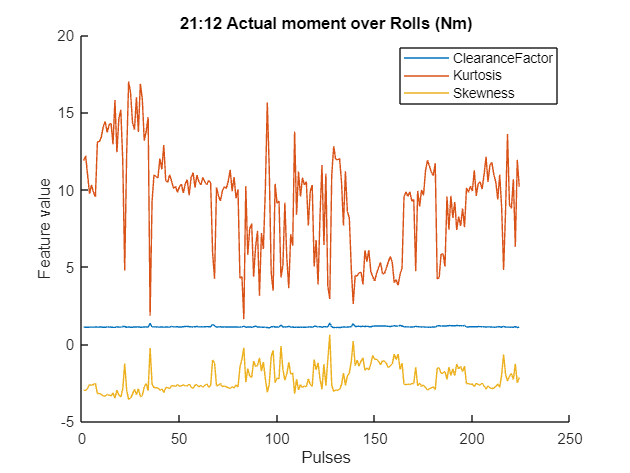

figure(); hold on;
title(sensorNames(selectedSignal));
xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxis = true;
for i = 1:numOfSelectedFeatures
    plot(selectedFeatureData{i});
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
legend(leg);

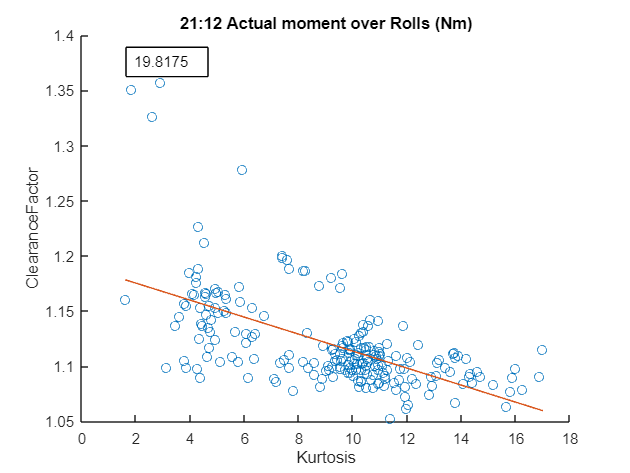

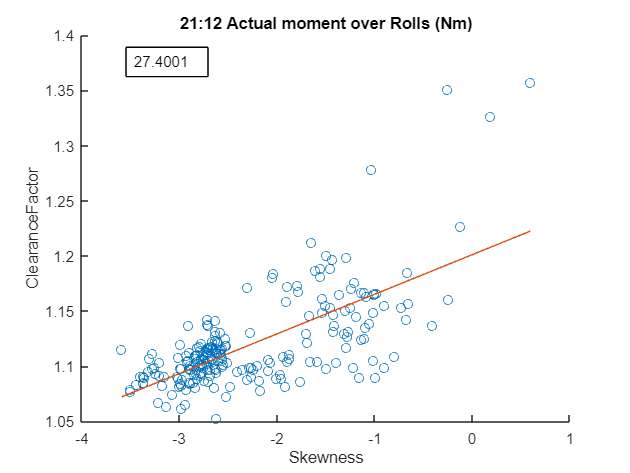

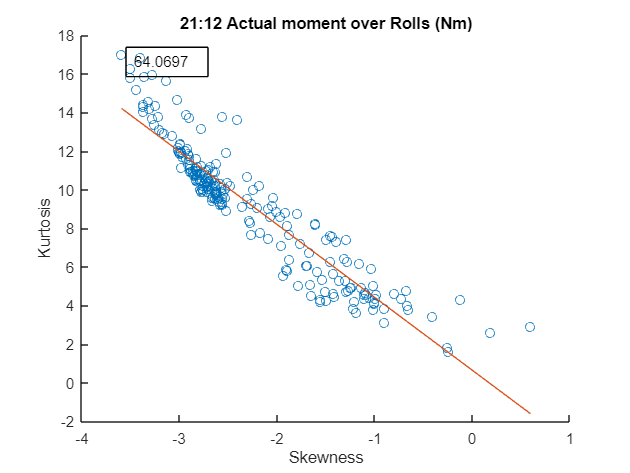

for index1 = 1 : numOfSelectedFeatures
    for index2 = index1 + 1 : numOfSelectedFeatures
        fnPlotModel( ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)) ...
            );
     end
end

1 2 3

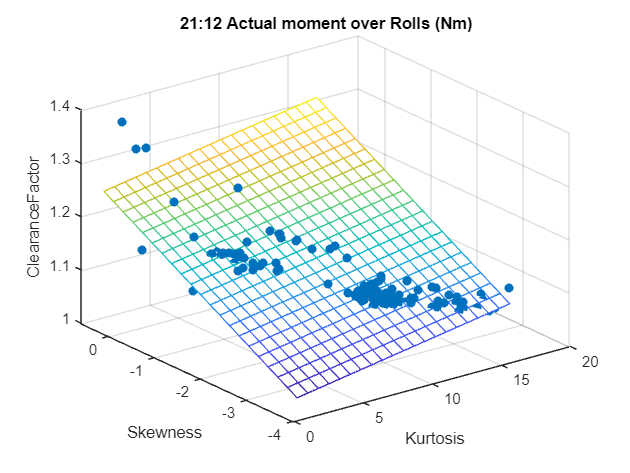

FIT = 28.450473

for index1 = 2 : numOfSelectedFeatures
    for index2 = index1+1 : numOfSelectedFeatures
        fprintf("%i %i %i", 1, index1, index2);
        Y_est = fnPlotModel3D( ...
            selectedFeatureData{1}, ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(1)), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)));
    end
end

## Combination 2

selectedFeature = 10;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

Sig 5 Sig 6 = 0.95
Sig 5 Sig 7 = 1.00
     5     6     7    10    14

     5    10    14



figure(); hold on;
title(sensorNames(selectedSignal));
xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [2]

secondaryAxisArrayIndex = 2

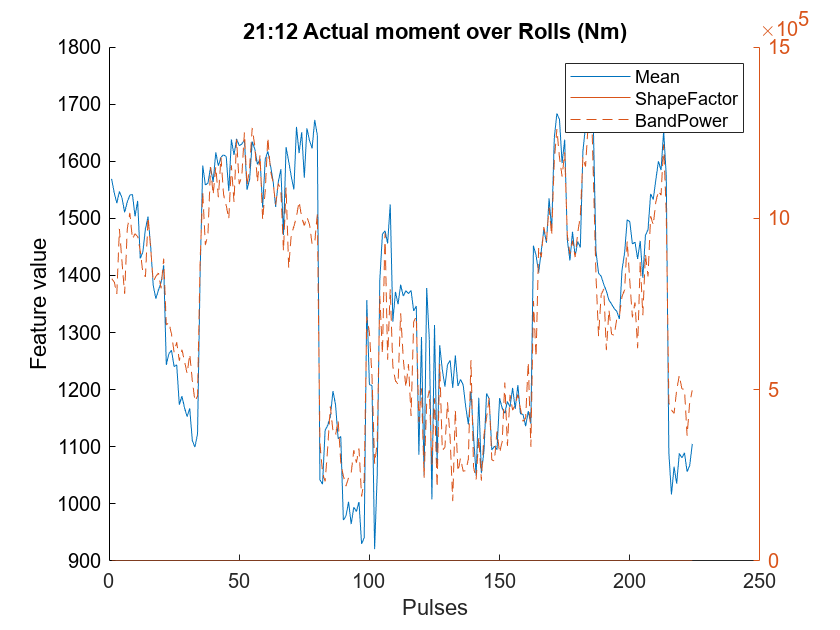

for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right
    end
    plot(selectedFeatureData{i});
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
legend(leg);

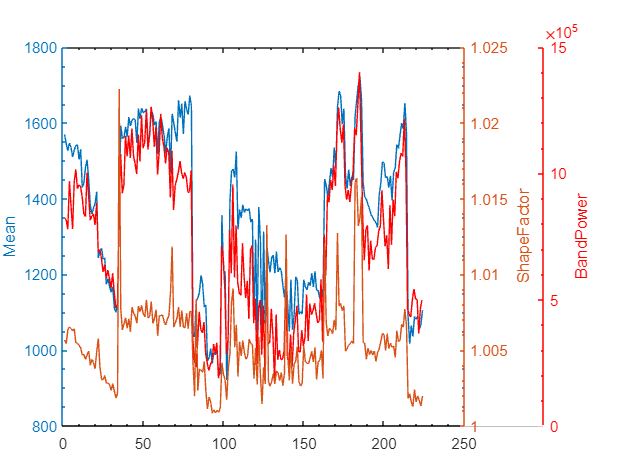

xx = 1:n;
plotyyy(xx', selectedFeatureData{1}, xx', selectedFeatureData{2}, xx', selectedFeatureData{3}, leg);

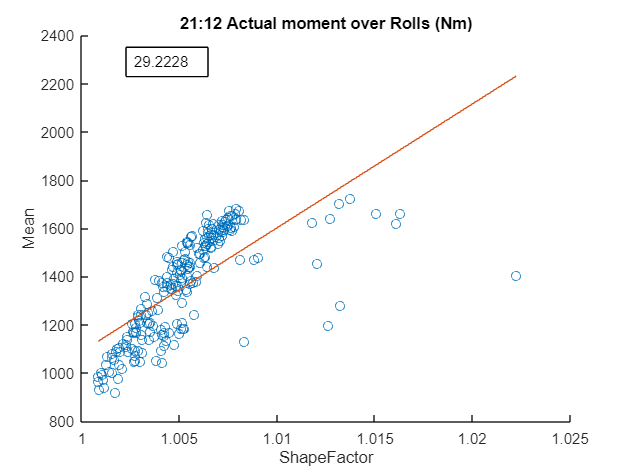

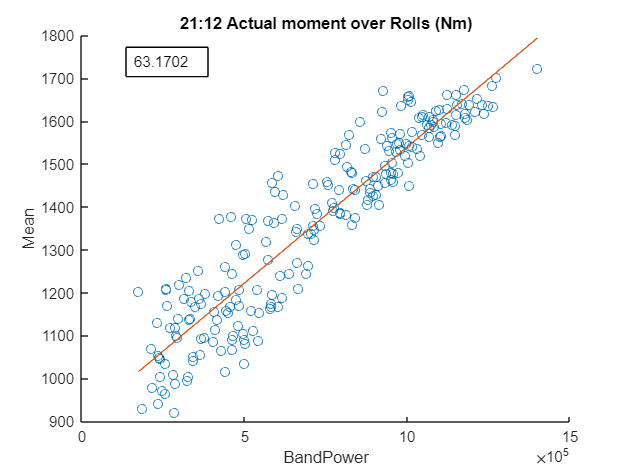

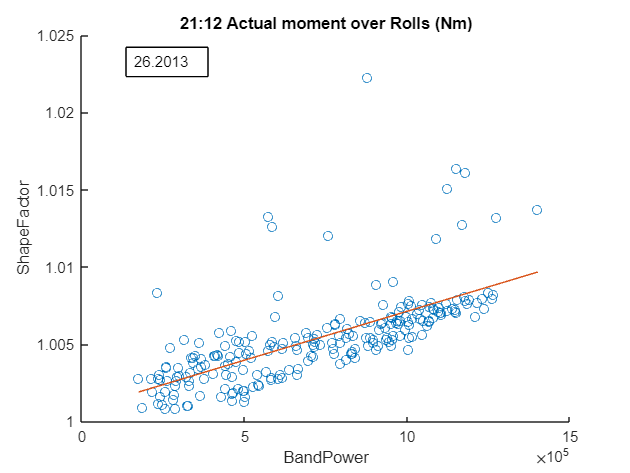

for index1 = 1 : numOfSelectedFeatures
    for index2 = index1 + 1 : numOfSelectedFeatures
        fnPlotModel( ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)) ...
            );
     end
end

1 2 3

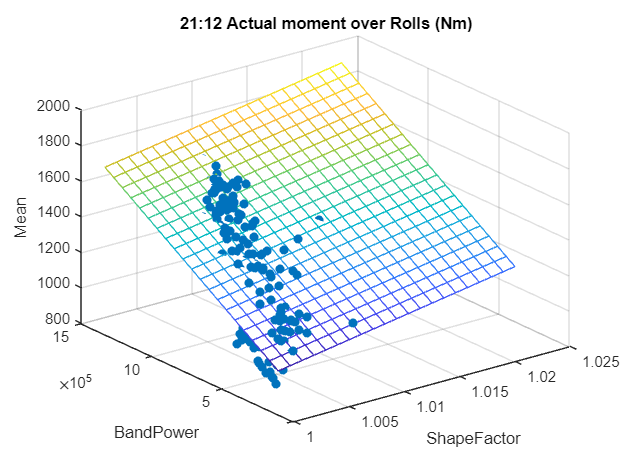

FIT = 64.762733

for index1 = 2 : numOfSelectedFeatures
    for index2 = index1+1 : numOfSelectedFeatures
        fprintf("%i %i %i", 1, index1, index2);
        Y_est = fnPlotModel3D( ...
            selectedFeatureData{1}, ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(1)), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)));
    end
end

## Combination 3

selectedFeature = 11;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

Sig 1 Sig 2 = 0.99
Sig 1 Sig 3 = 1.00
Sig 2 Sig 3 = 0.99


disp(selectedFeatureArray);

     1     2     3    11



     1    11



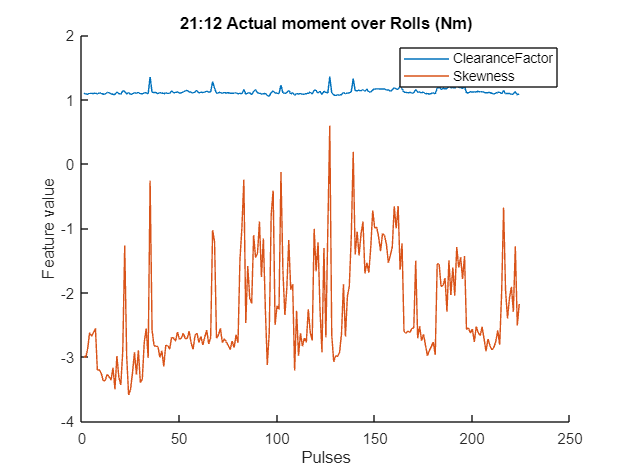

figure(); hold on;
leg = {numOfSelectedFeatures};
for i = 1:numOfSelectedFeatures
    plot(selectedFeatureData{i});
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
title(sensorNames(selectedSignal));
xlabel("Pulses");
ylabel("Feature value");
legend(leg);

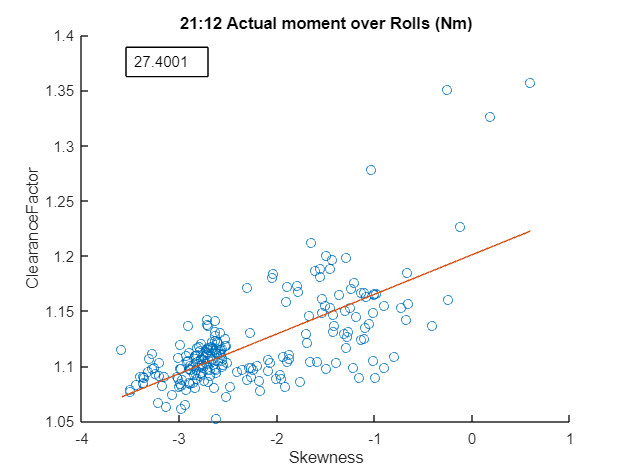

for index1 = 1 : numOfSelectedFeatures
    for index2 = index1 + 1 : numOfSelectedFeatures
        fnPlotModel( ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)) ...
            );
     end
end

## Combination 4

selectedFeature = 14;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

Sig 10 Sig 12 = 0.87


    10    12    14



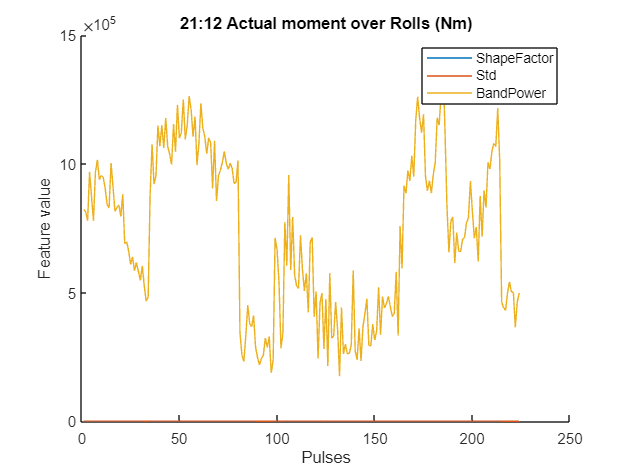

figure(); hold on;
leg = {numOfSelectedFeatures};
for i = 1:numOfSelectedFeatures
    plot(selectedFeatureData{i});
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
title(sensorNames(selectedSignal));
xlabel("Pulses");
ylabel("Feature value");
legend(leg);

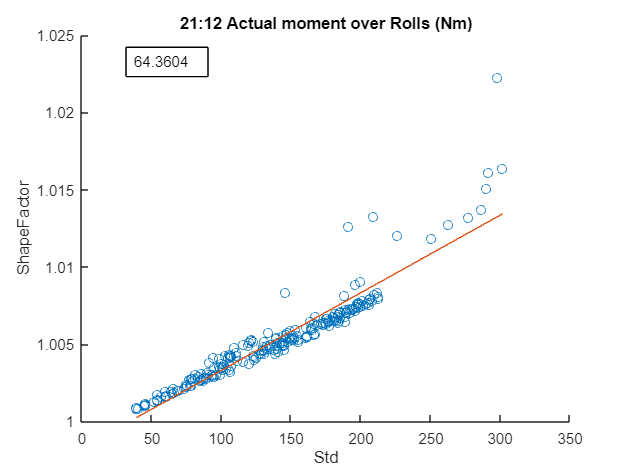

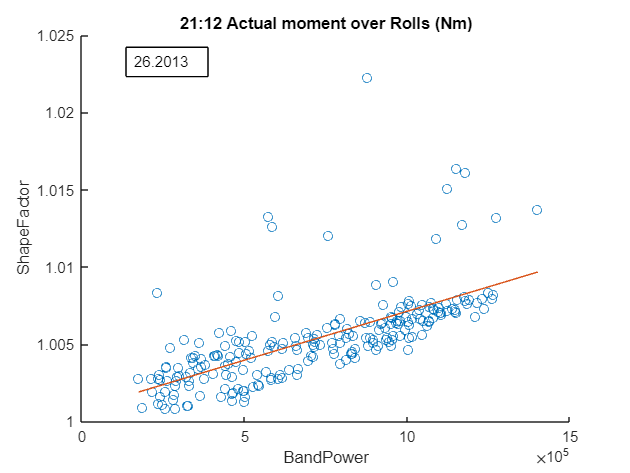

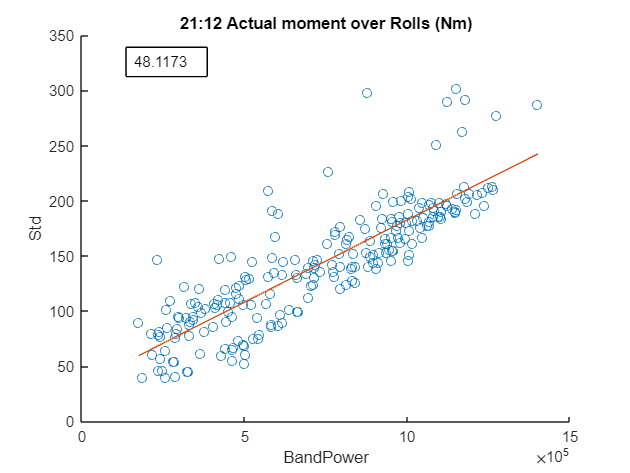

for index1 = 1 : numOfSelectedFeatures
    for index2 = index1 + 1 : numOfSelectedFeatures
        fnPlotModel( ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)) ...
            );
     end
end

1 2 3

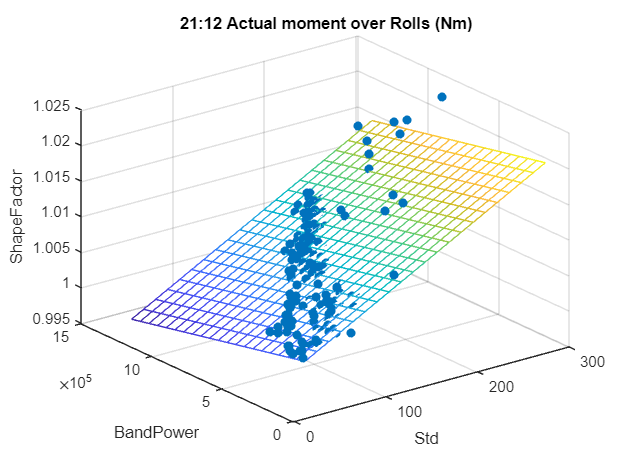

FIT = 73.549616

for index1 = 2 : numOfSelectedFeatures
    for index2 = index1+1 : numOfSelectedFeatures
        fprintf("%i %i %i", 1, index1, index2);
        Y_est = fnPlotModel3D( ...
            selectedFeatureData{1}, ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(1)), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)));
    end
end